# Random Sampling

Code to randomly sample data at sampling rates of 30, 60, and 90% from a ground truth data set and use Kriging to create predictions for the remaining data of each sample set.

### Step 1: Import and Process Data for Sampling

Load KCS_image_linear, x_grid, and y_grid from the Fig11b_linear.mat file

- x_grid: 256x1 array of x coordinates for KCS_image_linear

- y_grid: 256x1 array of y coordinates for KCS_image_linear

- KCS_image_linear: 256x256 array of data values

load Fig11b_linear

Convert the KCS_image_linear field to dB

KCS_image = 20*log10(KCS_image_linear);

Create matrix of x, y, and z coordinates

xy_grid = gridsamp([110 -250;360 0], 256);
xyz_values = [xy_grid KCS_image(:)];

### Step 2: Select Sampling Rate and Data Points

Sampling Rate

SAMP_RATE = .3

SAMP_RATE = 0.3000

Create Data Set Using Provided Sampling Rate

xyz = datasample(xyz_values, round(65536*SAMP_RATE), 'Replace', false);
xyz = sortrows(xyz, [1 2]);

### Step 3: Plot Sampled Points

Plot Sampled Data

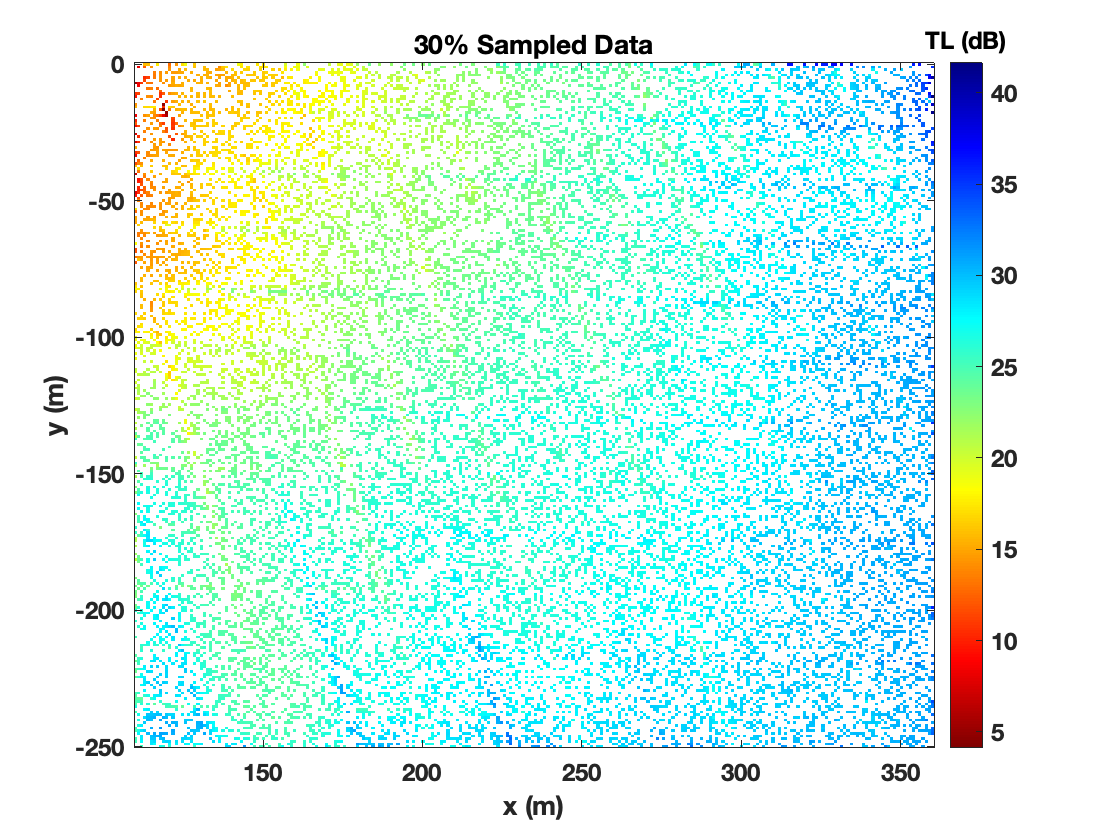

xyz_full = [xy_grid NaN(65536, 1)];
xyz_full(ismembertol(xyz_full(:,1:2), xyz(:,1:2),'ByRows',true), 3) = xyz(:, 3);

z = reshape(xyz_full(:,3),256,256);

figure
h = imagesc(x_grid, y_grid, z);
set(h,'alphadata',~isnan(z))
title('30% Sampled Data')
xlabel( 'x (m)')
ylabel('y (m)')
set(gca,'ydir','normal')
shading interp
colorbar
colormap(flipud(jet))
set(gca, 'FontSize',12,'FontWeight','bold')
h=colorbar; set(h, 'FontSize',12,'FontWeight','bold');
title(h, 'TL (dB)')

### Step 4: Graph Semivariogram for Data Points and Select Kriging Model

Graph the variogram for the sampled data

% d = variogram(xyz(:,1:2), xyz(:,3), 'plotit', true)

### Step 5: Create Kriging Model

Create kriging model for 30% sampled data

[dmodel, perf] = dacefit(xyz(:,1:2), xyz(:,3), @regpoly0, @corrgauss, 1);

### Step 6: Create Kriging Predictions and Graph

Predict and graph using the kriging model for the 30% data

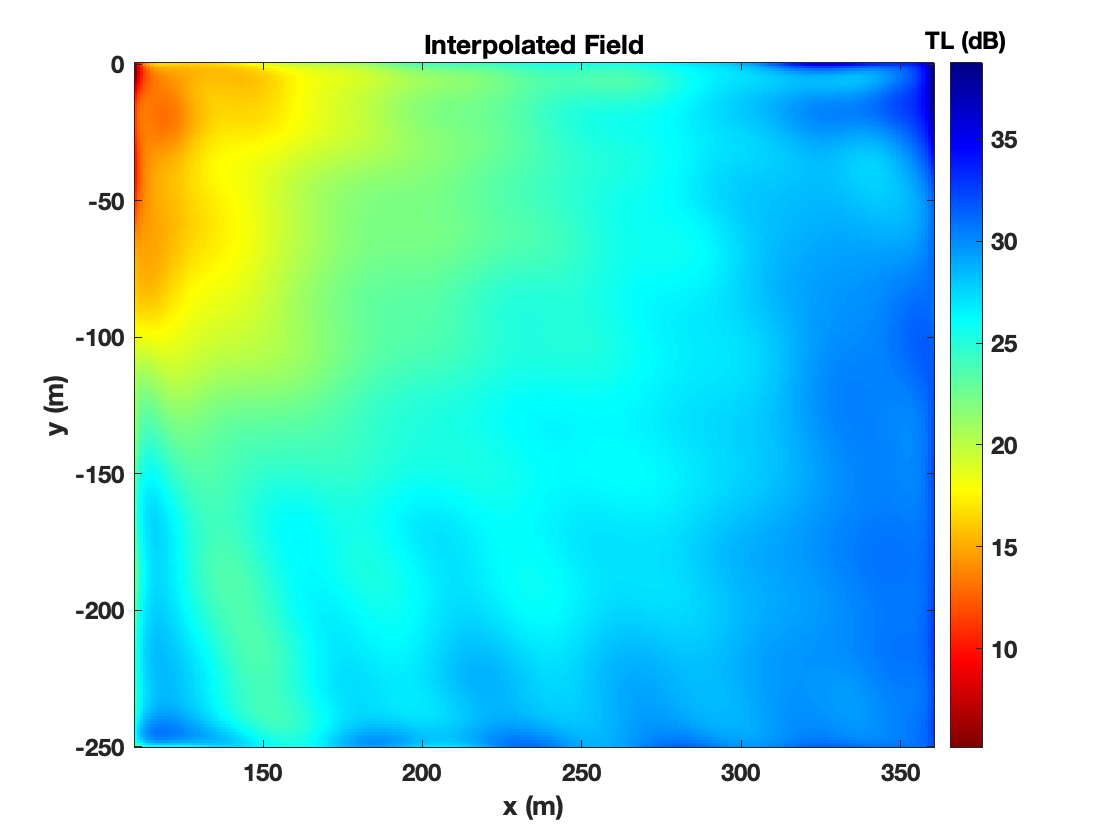

[YX, MSE] = predictor(xy_grid, dmodel);
YX = reshape(YX, 256, 256);
figure
h = imagesc(x_grid, y_grid, YX);
title('Interpolated Field')
xlabel( 'x (m)')
ylabel('y (m)')
set(gca,'ydir','normal')
shading interp
colorbar
colormap(flipud(jet))
set(gca, 'FontSize',12,'FontWeight','bold')
h=colorbar; set(h, 'FontSize',12,'FontWeight','bold');
title(h, 'TL (dB)')

### Step 7: Calculate PSNR